# Channel Estimation through deep learning : ChanNetEst

*ChanEstNet: A Deep Learning Based Channel Estimation for High-Speed Scenarios*,*Yong Liao, Yuanxiao Hua, Xuewu Dai†, Haimei Yao, Xinyi Yang*

The paper proposes the following neural network structure for channel estimation using pilots :

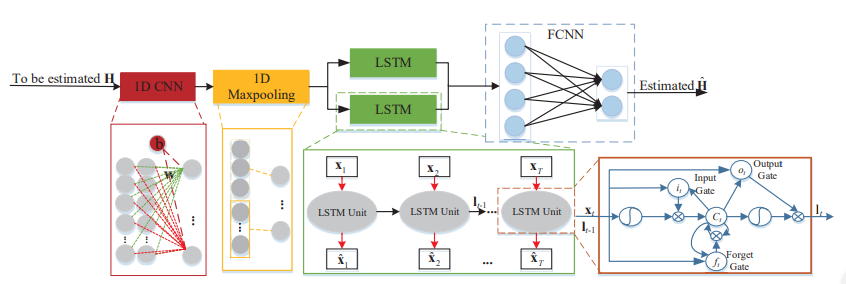

## Constructing the input data :

- We use SISO OFDM modulation for the input data with 4-QAM as the mapping technique.

- Cyclic prefix of length 16 is used to avoid ISI.

- Number of carriers is taken as $N_c$ = 64.

- We consider 20 symbols ($N_{s}$)  as one sub frame of the OFDM transmission. Each subframe has 4 pilots $N_p$ symbols evenly distributed.

nCarr = 64 ; % Number of carriers
cp_len = 16; % Length of cyclic prefix
nSym = 20;   % Number of symbols
Np = ceil(nSym/5); % Number of pilots
n_tx = 1 ;   % Number of transmitting antennaes
SNR = 20 ;   % Defning the SNR for the transmitted signals 

## Channel Modelling :

The channel array is already provided in the form of a .mat file which contains 16 taps evolving across time. 

For each 16 element channel array we convolve it with the OFDM symbol to get the channel distorted array.

We add AWGN noise to the this distorted array to get the final received array to which we apply deomulation and detection.

## Preprocessing the input data for the neural network:

- The received OFDM signal is demdoulated and the pilots are extracted

- LS estimate is used to predict the $\hat{H}[k]$  values for those subcarriers where the pilots are present.

- The incomplete input $\hat{H}$matrix is fed into the neural network. The matrix is a $N_{c}$  x $N_{s}$. So wherever the pilots are present in the each of the symbols we have the $\hat{H_{LS}}[k]$ values and for the rest of the $N_{c} x (N_{s} - N_{p})
$ elements we consider them to be zeros, whose values will be determined by the neural network

## Creating the training and validation data and labels :

- The traning data is created using the LSE function and the data input

- The training labels is taken from the *channel_train.mat* file

nSubFrame = 5000;
[H_train, H_labels] = trainingDataLabels_freq(nSym,nCarr,cp_len,n_tx,nSubFrame,SNR,Np);

batchSize = 200;

% Split real and imaginary grids into 2 image sets, then concatenate
H_train = cat(4,H_train(:,:,1,:),H_train(:,:,2,:));
H_labels = cat(4,H_labels(:,:,1,:),H_labels(:,:,2,:));

% Split into training and validation sets
valData = H_train(:,:,:,1:batchSize);
valLabels = H_labels(:,:,:,1:batchSize);

trainData = H_train(:,:,:,batchSize+1:end);
trainLabels = H_labels(:,:,:,batchSize+1:end);

%Validation Frequency(x) : Validate the network after x number of epochs
valFrequency  = round(size(trainData,4)/batchSize/5);

## Constructing the layers of the neural network:

The following are the layers present in the neural network :

- Data is reshaped into a 3D structure of $N_s$x $N_c$ x $2$, where the 2 layers in the 3D is for real and complex parts of H.

- Concatenating the data into a 2D structure of $N_s$x $2*N_c$

- One dimensional CNN : $N_s$x $2*N_c$

- One dimensional Maxpooling : $N_s$x $2*N_c$

Note : Only required for time domain estimation, where every H is nothing but L values in time domain. So we will have 2*Nc*L values

- BiLSTM structure : $N_s$x $4*N_c$

- Fully Connected Neural Network : $N_s$x $2*N_c$

- Reshaping it back to $N_c$x $N_s$ x $2$

layers = [...
    imageInputLayer([nSym,nCarr,1],'Normalization','none','Name','Input')
    convolution2dLayer([1,nCarr],nSym,'Name','CNN_1D')
    %regressionLayer
    tanhLayer('tanh')
    %sequenceInputLayer(nCarr,'Name','timeSequence')
    %bilstmLayer(nSym,'Name','bi-lstm')
    fullyConnectedLayer(2*nCarr,'Name','FCNN')
    regressionLayer
    ];
%lgraph =layerGraph(layers);


% Set up a training policy
options = trainingOptions('adam', ...
    'ExecutionEnvironment','multi-gpu',...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'MiniBatchSize',batchSize, ...
    'ValidationData',{valData, valLabels}, ...
    'ValidationFrequency',valFrequency, ...
    'ValidationPatience',5);
% Train the network. The saved structure trainingInfo contains the
% training progress for later inspection. This structure is useful for
% comparing optimal convergence speeds of different optimization
% methods.
[chanNetEst,trainingInfo] = trainNetwork(trainData, ...
                                          trainLabels,layers,options)
                                      
